# Ejercicios raíces

## Tanque esférico de radio R

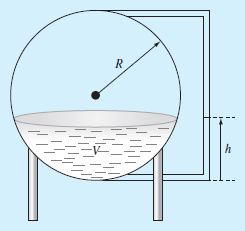


$$V=\pi h^2 \left(\frac{3R-h}{3}\right)$$


Queremos encontrar h tal $V=V_d$ deseada

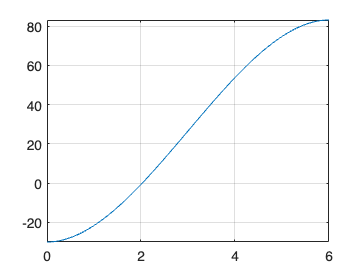

Vd = 30;
R = 3;

vol = @(h) (pi * h .^ 2) .* ((3 * R - h) / 3) - Vd;
fplot(vol, [0 6]);

grid on;


[h, i] = secante(vol, 1, 3)

h = 2.0269

i = 7

## Bungee jumper 

Determina la masa máxima que puede tener un saltador si, por motivos de seguridad, la velocidad no puede exceder de 33m/s a los 4s. 


$$v=\sqrt{g\frac{m}{c_d }\;}$$

$$\tanh \left(\sqrt{g\frac{c_d }{m}}\;t\right)$$


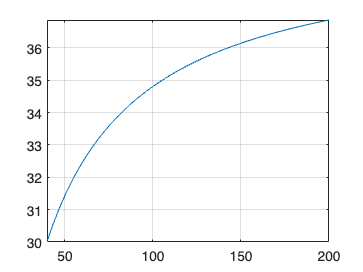

g = 9.81;
cd = 0.25;
vM = 33;
t = 4;

vol = @(m) sqrt(g * m / cd) .* tanh(sqrt(g * cd ./ m) * t);
fplot(vol, [40, 200]);

grid on;


mbj = secante(@(m) vol(m) - vM, 60, 80)

mbj = 66.6000

## Principio de Arquímedes y una esfera de radio r

De acuerdo con el principio de Arquímedes, la **fuerza de flotación** es igual al **peso del fluido desplazado** por la porción sumergida de un objeto. Para la esfera de corcho ilustrada en la siguiente figura, usa el método de bisección para determinar la altura h de la porción que queda encima del agua. Utiliza los siguientes valores para tu cálculo: r = 1m, densidad de la esfera ρe = 200kg/m3 y densidad del agua ρa= 1000kg/m3. Observa que el volumen de la porción de la esfera por encima del agua se puede calcular mediante

 
$$V=\frac{\pi h^2 }{3}\left(3r-h\right)$$


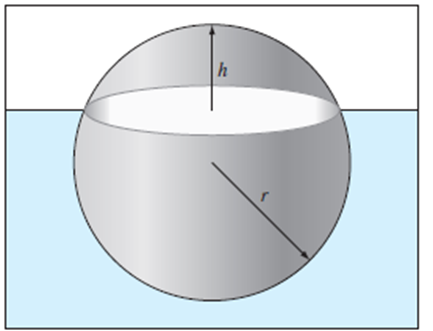

Para estar en equilibrio, la fuerza de flotación (que depende de h) debe ser igual al peso total de la esfera. Recuerda que F=mg y m=ρV. Por lo tanto, F = ρVg.

¿Peso de la esfera? ¿Volumen sumergido (desplazado)? ¿Fuerza de flotación? En equilibrio la fuerza total es cero. 

r = 1;
pe = 200;
pa = 1000;
vol = (4 / 3) * (pi * (r ^ 3))

vol = 4.1888

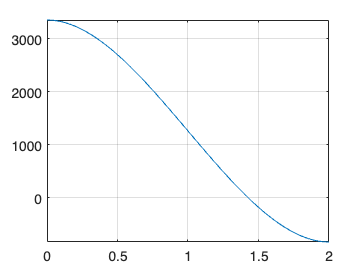


f = @(h) vol * (pa - pe) - pa * (pi * h .^ 2 / 3) .* (3 * r - h);
fplot(f, [0 2]);

grid on;


h = bisection(f, 0 , 2)

h = 1.4257


peso = vol * pe * g

peso = 8.2184e+03

Códigos:

function [x, i] = secante(f, xp, x)
    MAX_ITER = 53;
    REL_TOL = eps;
    i = 0;
    fx = f(x);
    fxp = f(xp);
    flag = true;
    while flag
        sn = (fx - fxp) / (x - xp);
        xp = x;
        fxp = fx;
        x = xp - fxp / sn;
        fx = f(x);
        i = i + 1;
        flag = i < MAX_ITER && abs((x - xp) / x) > REL_TOL;
    end
end

function [xr, i] = bisection(f, xl, xu)
    if sign(f(xl)) * sign(f(xu)) >= 0
    error('f(a) * f(b) < 0 no se satisface.')
    end
    MAX_ITER = 55;
    TOLER = eps;
    xr = (xl + xu) / 2;
    fx = f(xr);
    i = 0;
    while fx ~= 0 && abs((xu - xl) / xu) > TOLER && i < MAX_ITER
        if sign(f(xl)) == sign(fx)
        xl = xr;
        else
        xu = xr;
        end
        xr = (xl + xu) / 2;
        fx = f(xr);
        i = i + 1;
    end
end